# AlexNet CNN 

Óscar Poblete Sáenz

Course: Introduction to Artificial Intelligence

Teacher: Elizabeth Guevara Martinez

Note: Visit www.image-net.org to know what you can classify with this network

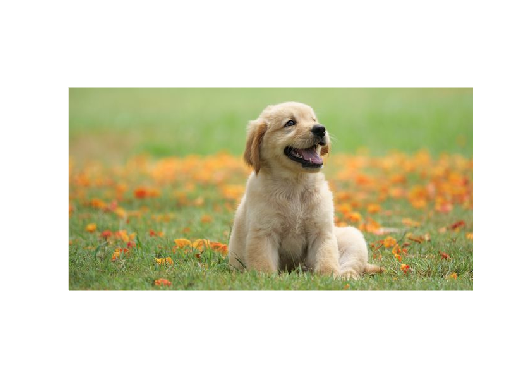

clear
clc

%Read image,
img=imread('dog.jpg');
imshow(img)

%Upload AlexNet model
net=alexnet();

%Get model layers
layers=net.Layers

layers =   25×1 Layer array with layers:

     1   'data'     Image Input                   227×227×3 images with 'zerocenter' normalization
     2   'conv1'    2-D Convolution               96 11×11×3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'    ReLU                          ReLU
     4   'norm1'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'    2-D Max Pooling               3×3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'    2-D Grouped Convolution       2 groups of 128 5×5×48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'    ReLU                          ReLU
     8   'norm2'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'    2-D Max Pooling               3×3 max pooling with stride [2  2] and padding [0  0

%Get input size that the CNN accepts
sz=layers(1).InputSize

sz =    227   227     3



%Check our image size
size(img)

ans =    321   640     3


%Scale the image
img2=imresize(img,sz(1:2)); %227x227, get the first two elements
size(img2)

ans =    227   227     3


%Classify image using model
[prediction,score]=classify(net,img2)%Check command window for classification result

prediction = categorical
     golden retriever 


score = 1×1000 single row vector
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
